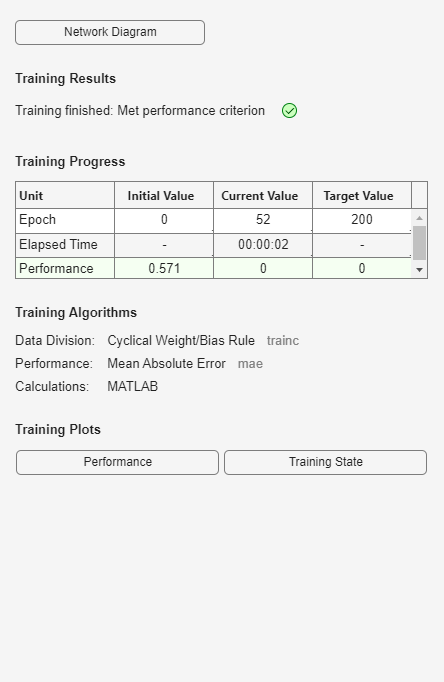

%感知器和MP模型
%国家类型的感知器判别
clear                                       %清理内存
P=[79.1	76.8 80.0 78.7 73.1 75.0 75.8 66.7 71.3	70.7 72.9 69.8 69.4 66.7
99.0 99.0 99.0 99.0 96.7 74.6 96.4 99.5	98.2 91.2 99.0 92.8 77.8 53.7
23582 29605 23257 25512	12013 17719	3967 6460 4809 6006 3353 4288 4036 3041]; 
                                            %输入变量
T=[1 1 1 1 1 1 0 0 0 0 0 0 0 0];            %目标输出
plotpv(P,T);                                %绘制训练样品立体图
Q=[78.7 78.2 70.2 68.0;99.0 96.9 97.9 82.8;
20659 13943	5648 3105];                     %输入待判样品信号
net=newp(minmax(P),1);                      %创建一个单输出的感知器网络
handle=plotpc(net.iw{1,1},net.b{1});        %初始权重和阈值绘图
net.trainParam.epochs=200;                  %指定最大训练次数
net=train(net,P,T);                         %按照目标T训练网络

Y=sim(net,Q)                                %仿真结果

Y =      1     1     0     0


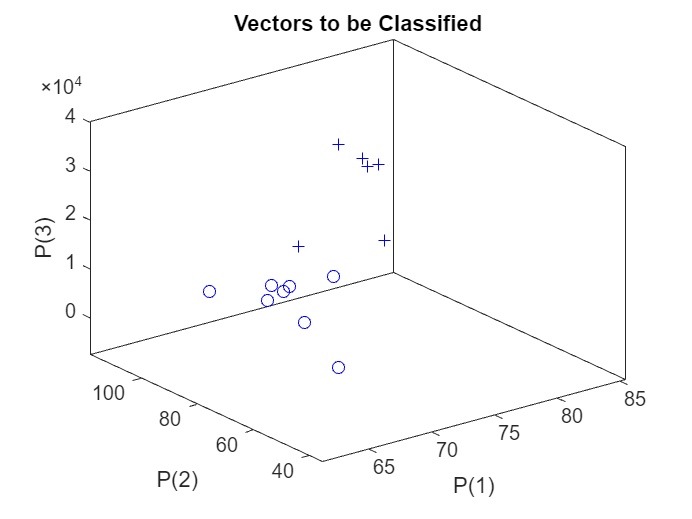

figure;                                     %保留误差曲线图
plotpv([P Q],[T Y]);                        %在训练样品分布图中添加待判样品
handle=plotpc(net.iw{1,1},net.b{1},handle); %在整体分类图中添加类型分界面

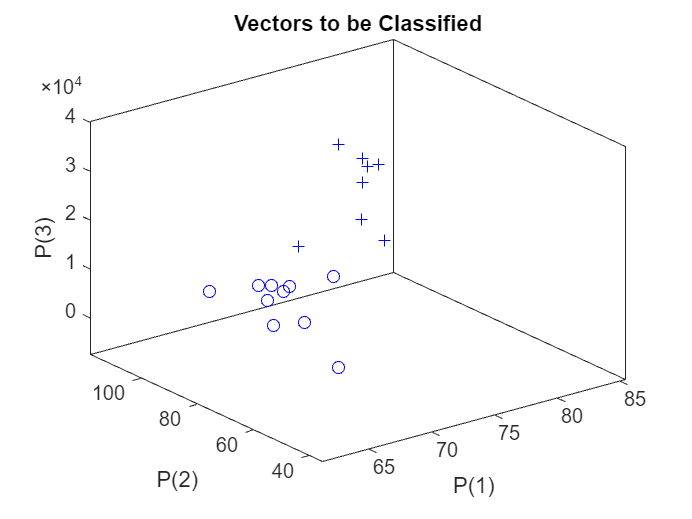

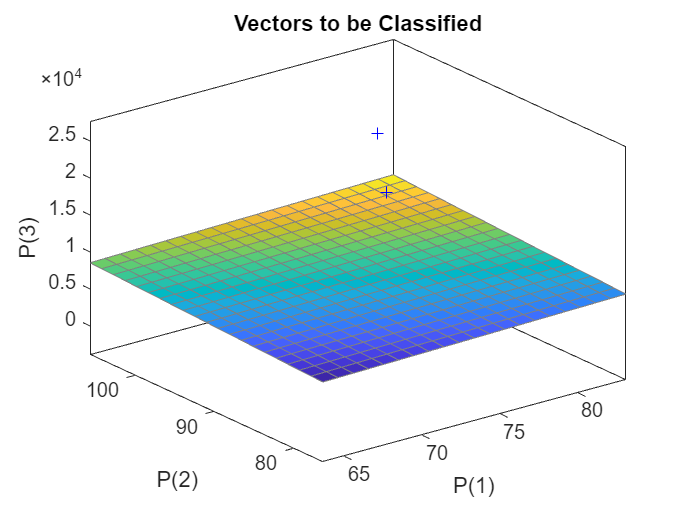

figure;                                     %保留整体分类图
plotpv(Q,Y);                                %绘出待判样品分布图
handle=plotpc(net.iw{1,1},net.b{1},handle); %在待判样品图中添加类型分界面

w=net.iw{1,1}                               %输出权数向量

w = 1.0e+04 *

   -1.2320   -1.7099    0.0303


b=net.b{1}                                  %输出阈值

b = -178